# 第5章 数字滤波器结构

## 5.4 无限长单位脉冲响应数字滤波器设计

### 5.4.3 巴特沃斯滤波器

#### Ch5_4_1

`绘制`巴特沃斯模拟滤波器振幅特性对阶数的依赖关系`图。`

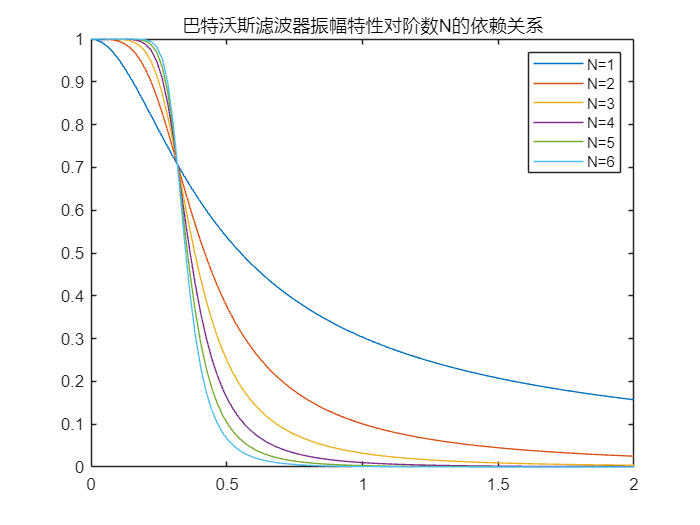

N = 6;
str = ["N=1","N=2","N=3","N=4","N=5","N=6"];
for n = 1:N
[z, p, k] = buttap(n);
[num,den] = zp2tf(z,p,k);
w = linspace(0, 2*pi); 
h = freqs(num,den,w);
mag = abs(h)/abs(h(1));
plot(w/pi,mag)
hold on; 
end
title('巴特沃斯滤波器振幅特性对阶数N的依赖关系')
legend(str(1),str(2),str(3),str(4),str(5),str(6));